# Lights

#### Common setup for all examples

ex_setup

Setup complete


#### Start timer

tic

#### Povlab object

pl = povlab( povray_version,...
             povray_path, ...
             povray_out_dir);

#### Scene

pl.scene_begin('scene_file', 'lights.pov', 'image_file', 'lights.png');
    pl.include("shapes");
    pl.global_settings("assumed_gamma 1");
    
    pl.camera('angle', 25, 'location', [20 35 15], 'look_at', [0 10 4.5], 'type', 'perspective');
    
    % Wall
    tex_mirror = pl.declare("tex_plane", pl.texture('pigment_odd', [0.3 0.3 0.3], 'pigment_even', [0.3 0.3 0.3], 'finish', "phong 1 reflection {0.80 metallic 0.4}"));
    pl.plane('normal', [1,0,0], 'distance', 0, 'texture', tex_mirror, 'scale', [1 1 1], 'rotate', [0 0 0], 'translate', [0 0 0]);

    % External light
    pl.light('location',  [20 35 15], 'color', [2 2 2]);
    
    % Lights
    s = 4;
    e = 14;
    n = e - s;
    for y = s:e
        r =  ((y - s) / n);
        pl.sphere('position', [2 y 2], 'radius', 0.4, 'texture', 'Yellow_Glass', 'scale', [1 1 1], 'rotate', [0 0 0], 'translate', [0 0 0]);
        pl.light('location',  [2 y 2], 'color', [r 0.4 0.4]);
    end

    for y = s:e
        g =  ((y - s) / e);
        pl.sphere('position', [2 y 3], 'radius', 0.4, 'texture', 'Dark_Green_Glass', 'scale', [1 1 1], 'rotate', [0 0 0], 'translate', [0 0 0]);
        pl.light('location',  [2 y 3], 'color', [0.4 g 0.4]);
    end

    for y = s:e
        g =  ((y - s) / e);
        pl.sphere('position', [2 y 4], 'radius', 0.4, 'texture', 'NBwinebottle', 'scale', [1 1 1], 'rotate', [0 0 0], 'translate', [0 0 0]);
        pl.light('location',  [2 y 4], 'color', [0.4 g 0.4]);
    end

    for y = s:e
        g =  ((y - s) / e);
        pl.sphere('position', [2 y 5], 'radius', 0.4, 'texture', 'NBoldglass', 'scale', [1 1 1], 'rotate', [0 0 0], 'translate', [0 0 0]);
        pl.light('location',  [2 y 5], 'color', [0.4 g 0.4]);
    end

    for y = s:e
        r =  ((y - s) / e);
        pl.sphere('position', [2 y 6], 'radius', 0.4, 'texture', 'NBglass', 'scale', [1 1 1], 'rotate', [0 0 0], 'translate', [0 0 0]);
        pl.light('location',  [2 y 6], 'color', [r 0.4 0.4]);
    end

    for y = s:e
        r =  ((y - s) / e);
        pl.sphere('position', [2 y 7], 'radius', 0.4, 'texture', 'Orange_Glass', 'scale', [1 1 1], 'rotate', [0 0 0], 'translate', [0 0 0]);
        pl.light('location',  [2 y 7], 'color', [r 0.4 0.4]);
    end

    for y = s:e
        r =  ((y - s) / e);
        pl.sphere('position', [2 y 8], 'radius', 0.4, 'texture', 'Vicks_Bottle_Glass', 'scale', [1 1 1], 'rotate', [0 0 0], 'translate', [0 0 0]);
        pl.light('location',  [2 y 8], 'color', [r 0.4 0.4]);
    end
    
pl.scene_end();

#### Render scene and show image

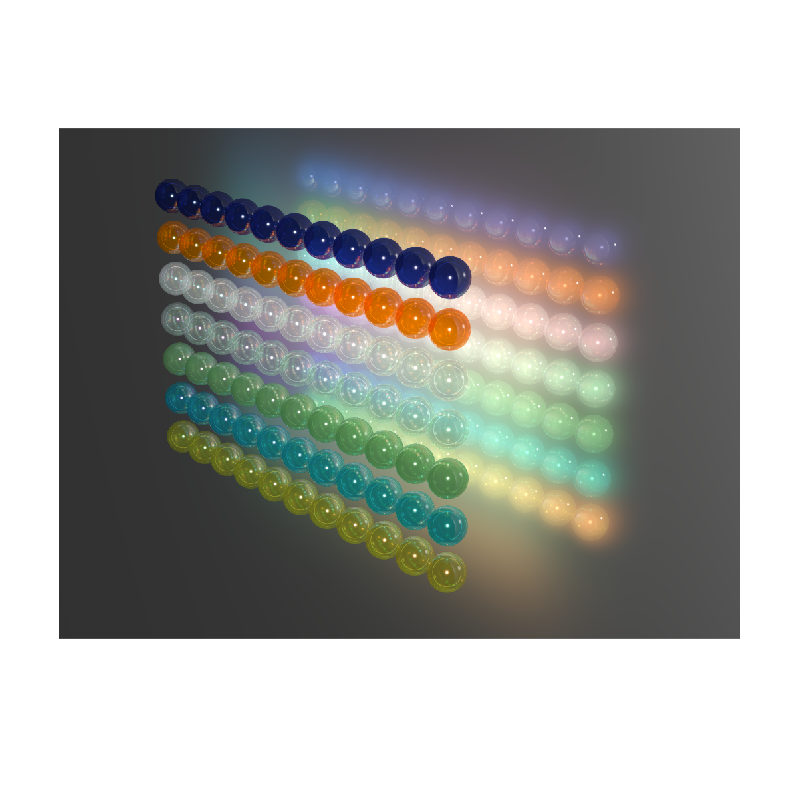

img = pl.render();
imshow(img);

#### Elapsed time

toc

Elapsed time is 1111.763543 seconds.
